clear
clf;
% 定义变量范围
D = linspace(0.09, 0.5, 100);  % D 的范围从 0 到 0.5
phi = linspace(0, 0.99, 100);  % phi 的范围从 0 到 1

% 创建网格
[D_grid, phi_grid] = meshgrid(D, phi);

% 预分配 M 的矩阵
inv_M = zeros(size(D_grid));

% 定义一个小的数值来避免分母为零
epsilon = 1e-6;  % 一个非常小的值，避免分母为零

% 计算不同情况下 M 的值
for i = 1:length(phi)
    for j = 1:length(D)
        % 获取当前的 D 和 phi
        D_val = D(j);
        phi_val = phi(i);
        
        % 计算当前条件下的分母
        denominator1 = 4*D_val + 4*phi_val - 1;
        denominator2 = -4*D_val - 4*phi_val + 3;
        denominator3 = -4*D_val - 4*phi_val + 3;
        denominator4 = 4*D_val + 4*phi_val - 5;
        
        % 避免分母为零的情况，通过加上 epsilon
        if (0 <= phi_val) && (phi_val < 0.5 - D_val)
            inv_M(i,j) =  (denominator1 + epsilon)/(2*D_val); 
        elseif (0.5 - D_val <= phi_val) && (phi_val < 0.5)
            inv_M(i,j) =  (denominator2 + epsilon)/(2*D_val);  
        elseif (0.5 <= phi_val) && (phi_val < 1 - D_val)
            inv_M(i,j) = (denominator3 + epsilon)/(2*D_val);  
        elseif (1 - D_val <= phi_val) && (phi_val < 1)
            inv_M(i,j) =(denominator4 + epsilon)/(2*D_val);  
        end
    end
end


% 限制 M 的范围在 -4 到 4 之间
 inv_M(inv_M < -4) = -4;
 inv_M(inv_M > 4) = 4;
% 计算 1/M
%inv_M = 1 ./ M;

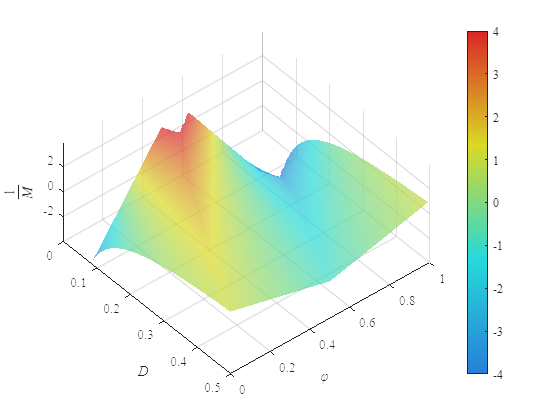


% 绘制结果
figure;
surf(D_grid, phi_grid, inv_M, 'FaceAlpha', 0.7);

% 禁用边框线
set(gca, 'FontName', 'Times New Roman');
%set(gca, 'EdgeColor', 'none'); % 这行可以去掉曲面连接线

% 设置颜色映射
n = 256; % 定义颜色分辨率
cmap = [linspace(0, 0, n/4)', linspace(0.5, 1, n/4)', linspace(1, 1, n/4)'; ... % 蓝到绿
        linspace(0, 1, n/4)', linspace(1, 1, n/4)', linspace(1, 0, n/4)'; ... % 绿到黄
        linspace(1, 1, n/4)', linspace(1, 0, n/4)', linspace(0, 0, n/4)'];    % 黄到红
gray_level = 0.5; % 接近灰色的值（0.5是中性灰）
desaturated_cmap = cmap * 0.7 + gray_level * (1 - 0.7); % 线性插值降低饱和度
colormap(desaturated_cmap);
colorbar;

% 平滑显示
shading interp;  % 平滑插值

% 设置视角和网格
view(50,60); % 设置视角
grid on;
hold on;
% 添加标题和标签
xlabel('\it{D}');
ylabel('\it{φ}');
zlabel('$\frac{1}{M}$', 'Interpreter', 'latex');
zlim([-3.99,3.99])

hold on;

%contour3(D_grid, phi_grid, M, [1, 1], 'LineWidth', 2, 'LineColor', 'k');
%text(0.2, 0.7, 4, 'ZVS Region', 'FontSize', 12, 'Color', 'black', 'HorizontalAlignment', 'center');
%text(0.35, 0.02, 0, 'Non-ZVS Region', 'FontSize', 12, 'Color', 'black', 'HorizontalAlignment', 'center');


% 箭头指离'Non-ZVS Region'文本
%annotation('arrow', [0.35, 0.35], [0.3, 0.2], 'Color', 'black', 'LineWidth', 2);
% 箭头指向'ZVS Region'文本
%annotation('arrow', [0.47, 0.47], [0.75, 0.85], 'Color', 'black', 'LineWidth', 2);

% 使用 'Arrow' 样式绘制箭头
%text(0.43, 0.7, 0, 'Non-ZVS Region', 'FontSize', 12, 'Color', 'black', 'HorizontalAlignment', 'center');
%text(0.25, 0.5, 0.8, 'ZVS Region', 'FontSize', 12, 'Color', 'black', 'HorizontalAlignment', 'center');

% 绘制更加美观的箭头
%annotation('textarrow', [0.35, 0.35], [0.3, 0.2], 'String', 'Non-ZVS Region', 'FontSize', 12, 'Color', 'black', 'LineWidth', 2, 'HeadWidth', 15, 'HeadLength', 10);
%annotation('textarrow', [0.47, 0.47], [0.75, 0.85], 'String', 'ZVS Region', 'FontSize', 12, 'Color', 'black', 'LineWidth', 2, 'HeadWidth', 15, 'HeadLength', 10);

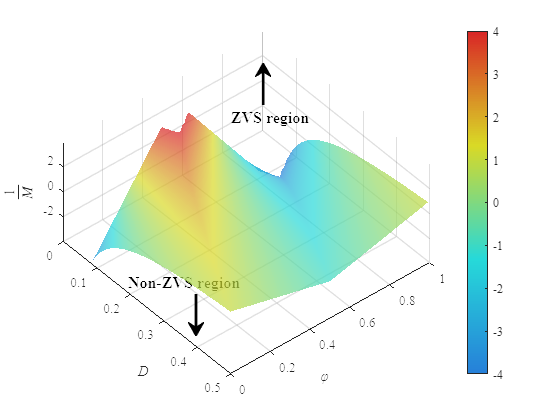

% 绘制文本时更改为 Times New Roman 字体
text(0.2, 0.7, 4, 'ZVS region', 'FontSize', 12, 'FontName', 'Times New Roman', 'FontWeight', 'bold', 'Color', 'black', 'HorizontalAlignment', 'center');
text(0.35, 0.02, 0, 'Non-ZVS region', 'FontSize', 12, 'FontName', 'Times New Roman', 'FontWeight', 'bold', 'Color', 'black', 'HorizontalAlignment', 'center');

% 只绘制箭头，删除文本
annotation('arrow', [0.35, 0.35], [0.3, 0.2], 'LineWidth', 2, 'HeadWidth', 15, 'HeadLength', 10, 'Color', 'black');
annotation('arrow', [0.47, 0.47], [0.75, 0.85], 'LineWidth', 2, 'HeadWidth', 15, 'HeadLength', 10, 'Color', 'black');

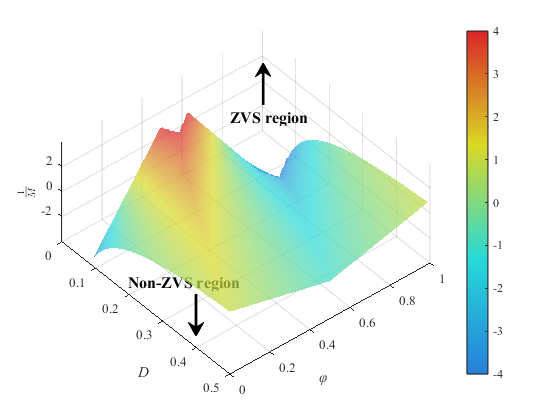

% 导出为 PDF 格式，设置输出尺寸
exportgraphics(gcf, 'ZVSLowVoltageSideS1S33DMode3.pdf', 'ContentType', 'image', 'BackgroundColor', 'none');